# Optimization of Link Lengths

## Initialisation


close all;
clear all;
clc;

syms alpha0 a0 d0 d1 t1 alpha1 a1 d2 t2 alpha2 a2 d3 t3 alpha3 a3 d4 t4 alpha4 a4 d5 t5 x y z L1 L2


## DH Parameters Definition and Transformation Matrix


DH = [0         0           0      t1; % alpha, a, d, theta - Symbolic
      0         L1      0       t2;
      0         L2       0       t3;
      0         0           0      0];

T_01 = transformationMatrix(DH(1,:));
T_12 = transformationMatrix(DH(2,:));
T_23 = transformationMatrix(DH(3,:));
T_34 = transformationMatrix(DH(4,:));

T_04 = T_01*T_12*T_23*T_34;
T_04 = simplify(T_04)

$$T\_04 = \left(\begin{array}{cccc} \cos\left(t_{1}+t_{2}+t_{3}\right) & -\sin\left(t_{1}+t_{2}+t_{3}\right) & 0 & L_{2}\,\cos\left(t_{1}+t_{2}\right)+L_{1}\,\cos\left(t_{1}\right)\\ \sin\left(t_{1}+t_{2}+t_{3}\right) & \cos\left(t_{1}+t_{2}+t_{3}\right) & 0 & L_{2}\,\sin\left(t_{1}+t_{2}\right)+L_{1}\,\sin\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

[R_01, P_01] = tr2rt(T_01); R_10 = transpose(R_01);
[R_12, P_12] = tr2rt(T_12); R_21 = transpose(R_12);
[R_23, P_23] = tr2rt(T_23); R_32 = transpose(R_23);
[R_34, P_34] = tr2rt(T_34); R_43 = transpose(R_34);
[R_04, P_04] = tr2rt(T_04);


## Jacobian from direct differentiation

T_02 = T_01*T_12;
T_03 = T_02*T_23;
[R_02, P_02] = tr2rt(T_02); R_20 = transpose(R_02);
[R_03, P_03] = tr2rt(T_03); R_30 = transpose(R_01);

J0_DD = sym(zeros(6,3));
J0_DD(:,1) = [cross(R_01(:, 3), (P_04 - P_01));R_01(:,3)];
J0_DD(:,2) = [cross(R_02(:, 3), (P_04 - P_02));R_02(:,3)];
J0_DD(:,3) = [cross(R_03(:, 3), (P_04 - P_03));R_03(:,3)];
J0_DD = simplify(J0_DD)

$$J0\_DD = \left(\begin{array}{ccc} -L_{2}\,\sin\left(t_{1}+t_{2}\right)-L_{1}\,\sin\left(t_{1}\right) & -L_{2}\,\sin\left(t_{1}+t_{2}\right) & 0\\ L_{2}\,\cos\left(t_{1}+t_{2}\right)+L_{1}\,\cos\left(t_{1}\right) & L_{2}\,\cos\left(t_{1}+t_{2}\right) & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

J0 = J0_DD;

% We are simplifying the Jacobian for optimization
J0S = [J0(1:2, :); J0(6,:)]

$$J0S = \left(\begin{array}{ccc} -L_{2}\,\sin\left(t_{1}+t_{2}\right)-L_{1}\,\sin\left(t_{1}\right) & -L_{2}\,\sin\left(t_{1}+t_{2}\right) & 0\\ L_{2}\,\cos\left(t_{1}+t_{2}\right)+L_{1}\,\cos\left(t_{1}\right) & L_{2}\,\cos\left(t_{1}+t_{2}\right) & 0\\ 1 & 1 & 1 \end{array}\right)$$

J0 = J0S;
J0T = transpose(J0)

$$J0T = \left(\begin{array}{ccc} -L_{2}\,\sin\left(t_{1}+t_{2}\right)-L_{1}\,\sin\left(t_{1}\right) & L_{2}\,\cos\left(t_{1}+t_{2}\right)+L_{1}\,\cos\left(t_{1}\right) & 1\\ -L_{2}\,\sin\left(t_{1}+t_{2}\right) & L_{2}\,\cos\left(t_{1}+t_{2}\right) & 1\\ 0 & 0 & 1 \end{array}\right)$$

JJT = simplify(J0*J0T)

$$JJT = \begin{array}{l} \left(\begin{array}{ccc} {L_{2}}^{2}\,{\sin\left(t_{1}+t_{2}\right)}^{2}+{\left(L_{2}\,\sin\left(t_{1}+t_{2}\right)+L_{1}\,\sin\left(t_{1}\right)\right)}^{2} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & {L_{2}}^{2}\,{\cos\left(t_{1}+t_{2}\right)}^{2}+{\left(L_{2}\,\cos\left(t_{1}+t_{2}\right)+L_{1}\,\cos\left(t_{1}\right)\right)}^{2} & \sigma_{3}\\ \sigma_{2} & \sigma_{3} & 3 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\sin\left(2\,t_{1}\right)\,{L_{1}}^{2}}{2}-\sin\left(2\,t_{1}+t_{2}\right)\,L_{1}\,L_{2}-\sin\left(2\,t_{1}+2\,t_{2}\right)\,{L_{2}}^{2}\\ \sigma_{2}=-2\,L_{2}\,\sin\left(t_{1}+t_{2}\right)-L_{1}\,\sin\left(t_{1}\right)\\ \sigma_{3}=2\,L_{2}\,\cos\left(t_{1}+t_{2}\right)+L_{1}\,\cos\left(t_{1}\right) \end{array}$$

## Workspace and Link dimensions

l1 = [0.01:0.01:0.5];
l2 = [0.01:0.01:0.5];
h = 0.1;
w = 0.14;
d = 0.2;
count = 0;
kappa_array = [];
C= [];
l1_plot = [];
l2_plot = [];

X= linspace(d, d+w, 15);
Y= linspace(-h/2, h/2, 11);


## Optimization Algorithm

% It takes long time to run. If you don't wanna run this 
% just load C.mat, l1_plot.mat and l2_plot.mat from 'Data' 
% directory into the workspace

for i=1:length(l1)
    for j=1:length(l2)
        kappa_array = [];
        if (abs(l1(i)-l2(j)) < d) && (l1(i)+l2(j) > ((d+w)^2 + (h/2)^2)^0.5)
            count = count+1;
            for m=1:length(X)
                for n=1:length(Y)
                    [theta] = inverseKinematicsScara3(X(m), Y(n), l1(i), l2(j));
                    JJTsubs = subs(JJT, [t1, t2, L1, L2], [theta(1), theta(2), l1(i), l2(j)]);
                    JJTsubs = vpa(JJTsubs);
                    lambda = eig(JJTsubs);
                    lambda_max = max(lambda);
                    lambda_min = min(lambda);
                    kappa = vpa((lambda_min/lambda_max)^0.5);
                    kappa_array = [kappa_array; kappa];
                end
            end
            C(count) = (sum(kappa_array)*min(kappa_array))/(l1(i)^3 + l2(j)^3);
            l1_plot(count) = l1(i);
            l2_plot(count) = l2(j);
            fprintf('Count = %d \t C-Value = %f \n',count, C(count));
        end
    
    end
end

Count = 1 	 C-Value = 2.601856 
Count = 2 	 C-Value = 3.518745 
Count = 3 	 C-Value = 5.045907 
Count = 4 	 C-Value = 3.523451 
Count = 5 	 C-Value = 4.524515 
Count = 6 	 C-Value = 6.597086 
Count = 7 	 C-Value = 7.460594 
Count = 8 	 C-Value = 5.812717 
Count = 9 	 C-Value = 3.685446 
Count = 10 	 C-Value = 5.623201 
Count = 11 	 C-Value = 8.294849 
Count = 12 	 C-Value = 9.512729 
Count = 13 	 C-Value = 9.956593 
Count = 14 	 C-Value = 8.093066 
Count = 15 	 C-Value = 5.962094 
Count = 16 	 C-Value = 3.750795 
Count = 17 	 C-Value = 6.793851 
Count = 18 	 C-Value = 10.121806 
Count = 19 	 C-Value = 11.736132 
Count = 20 	 C-Value = 12.437002 
Count = 21 	 C-Value = 12.537155 
Count = 22 	 C-Value = 10.421550 
Count = 23 	 C-Value = 8.174658 
Count = 24 	 C-Value = 5.986129 
Count = 25 	 C-Value = 3.748998 
Count = 26 	 C-Value = 7.992677 
Count = 27 	 C-Value = 12.025732 
Count = 28 	 C-Value = 14.085594 
Count = 29 	 C-Value = 15.086243 
Count = 30 	 C-Value = 15.383041 
Count = 31

## Plotting C vs L1 vs L2

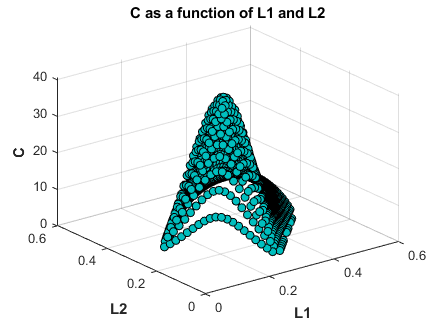

scatter3(l1_plot,l2_plot,C, 'filled', 'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
xlabel('L1', 'FontWeight','bold')
ylabel('L2', 'FontWeight','bold')
zlabel('C', 'FontWeight','bold')
title('C as a function of L1 and L2', 'FontWeight','bold')

% saveas(gcf,'CPlot.fig')

## Finding maximum in C

[Cmax,Imax] = max(C)

Cmax = 40.6784

Imax = 278

L1_max = l1_plot(Imax)

L1_max = 0.2400

L2_max = l2_plot(Imax)

L2_max = 0.2400

kappa_max = [];
for m=1:length(X)
    for n=1:length(Y)
        [theta] = inverseKinematicsScara3(X(m), Y(n), L1_max, L2_max);
        JJTsubs = subs(JJT, [t1, t2, L1, L2], [theta(1), theta(2), L1_max, L2_max]);
        JJTsubs = vpa(JJTsubs);
        lambda = eig(JJTsubs);
        lambda_max = max(lambda);
        lambda_min = min(lambda);
        kappa = vpa((lambda_min/lambda_max)^0.5);
        kappa_max(m,n) = kappa;
    end
end

## Plotting kappa at C_max

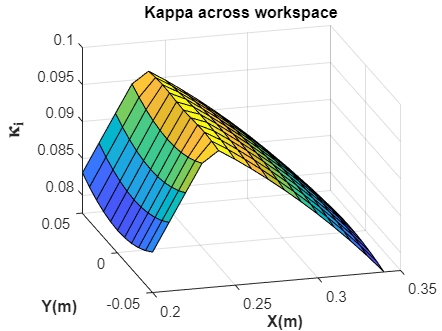

surf(X,Y, kappa_max')
xlabel('X(m)', 'FontWeight','bold')
ylabel('Y(m)', 'FontWeight','bold')
zlabel('$\mathbf{\kappa_i}$', 'Interpreter', 'Latex', 'FontWeight','bold', 'FontSize', 14)
title('Kappa across workspace', 'FontWeight','bold')

% The plot is symmetric about Y=0 (or X-axis). This is because the 
% the workspace is itself symmetric with respect to the 
% manipulator about Y=0 (or X-axis). 
% 
% The best manipulability points are at around X=0.24 m (somewhere
% close to the middle), and worst manipulability points are at 
% Xmin(X=0.2 m) and Xmax(0.34 m) values within the workspace.
% If we look more closely, we see local minimums at
% (1) (|X|min, |Y|min) i.e. (0.2, 0)
% (2) (|X|max, |Y|max) i.e. (0.34, 0.5) and (0.34, -0.5)
% These are the points which are either the closest or the farthest
% from the manipulator
% Hence we see low manipulability are closer points and farther 
% points within the workspace. 
% 
% The same points mentioned above (with low manipulability)
% are closer to the singularity of the workspace. 
% (1) (|X|min, |Y|min) i.e. (0.2, 0)
% (2) (|X|max, |Y|max) i.e. (0.34, 0.5) and (0.34, -0.5)

